%% Reissner-Nordstrom 黑洞轨道进动模拟 (基于近心点/短轴计算)
clear; clc; close all;

% --- 1. 物理参数 ---
M = 1;              
Q = 0.5;            % 电荷 (Q < M)
r_h = M + sqrt(M^2 - Q^2); % 外视界半径 (Event Horizon)

% --- 2. 初始条件 (Bound Orbit) ---
r_0 = 12 * M;       % 初始半径
L = 4.0 * M;        % 角动量
E = 0.97;           % 能量 (E < 1 为束缚轨道)

% 计算初始径向动量 (由哈密顿量约束 H = -1/2)
f_func = @(r) 1 - 2*M./r + Q^2./r.^2;
f_0 = f_func(r_0);
term = (E^2/f_0 - 1 - L^2/r_0^2) / f_0;

if term < 0
    error('当前能量和角动量下，初始位置处于势垒禁止区，请调整参数。');
end
pr_0 = sqrt(term);    

% 初始状态向量: [t, r, theta, phi, pt, pr, ptheta, pphi]
u0 = [0; r_0; pi/2; 0; -E; pr_0; 0; L];

% --- 3. 符号推导正则方程 (Hamiltonian Mechanics) ---
fprintf('正在推导 RN 度规下的测地线方程...\n');

正在推导 RN 度规下的测地线方程...


syms t r th ph pt pr pth pph real
f_s = 1 - 2*M/r + Q^2/r^2;
% 逆变度规分量 g^uv
g_up = diag([-1/f_s, f_s, 1/r^2, 1/(r^2*sin(th)^2)]);
H_sym = 0.5 * [pt pr pth pph] * g_up * [pt; pr; pth; pph];

vars = [t; r; th; ph; pt; pr; pth; pph];
eqs = [diff(H_sym, pt);  diff(H_sym, pr);  diff(H_sym, pth); diff(H_sym, pph);
       -diff(H_sym, t); -diff(H_sym, r); -diff(H_sym, th); -diff(H_sym, ph)];
odefun = matlabFunction(eqs, 'Vars', {sym('tau'), vars});

% --- 4. 数值模拟 ---
fprintf('正在求解轨道...\n');

正在求解轨道...


% 事件设置：1. 坠入视界停止； 2. 动量极值捕捉（不停止）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-12, ...
                 'Events', @(t,u) orbit_events(t, u, r_h));

[tau_out, sol] = ode45(odefun, [0 1200], u0, options);

% --- 5. 进动角分析 (计算近心点/短轴点) ---
r_sol = real(sol(:, 2));
phi_sol = real(sol(:, 4));

% 寻找极小值 (近心点 Periastron)
% 通过对 -r 寻找峰值来找到 r 的最小值
[~, locs_min] = findpeaks(-r_sol);

if length(locs_min) >= 2
    phi_mins = phi_sol(locs_min);
    delta_phi = diff(phi_mins);        % 相邻近心点的方位角差
    prec_rad = delta_phi - 2*pi;       % 进动角 (rad)
    avg_prec_deg = mean(rad2deg(prec_rad)); 
    
    fprintf('--------------------------------------\n');
    fprintf('基于近心点(Periastron)的分析报告:\n');
    fprintf('检测到完整周期数: %d\n', length(prec_rad));
    fprintf('平均单圈进动角: %.4f 度\n', avg_prec_deg);
    fprintf('--------------------------------------\n');
else
    avg_prec_deg = 0;
    warning('未检测到足够的近心点。请尝试增加模拟时间或减小初始能量 E。');
end

--------------------------------------


基于近心点(Periastron)的分析报告:


检测到完整周期数: 1


平均单圈进动角: 137.3084 度


--------------------------------------


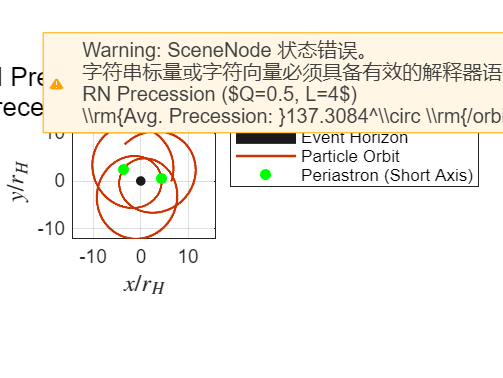


% --- 6. 绘图与可视化 ---
r_norm = r_sol ./ r_h; 
x_norm = r_norm .* cos(phi_sol);
y_norm = r_norm .* sin(phi_sol);

figure('Color', 'w', 'Name', 'RN Black Hole Periastron Precession'); 
ax = axes; hold on;

% 1. 绘制视界 (Event Horizon)
theta_circle = linspace(0, 2*pi, 100);
fill(cos(theta_circle), sin(theta_circle), [0.1 0.1 0.1], 'EdgeColor', 'none', 'DisplayName', 'Event Horizon');

% 2. 绘制轨道
plot(x_norm, y_norm, 'Color', [0.8 0.2 0], 'LineWidth', 1.2, 'DisplayName', 'Particle Orbit');

% 3. 标注近心点 (短轴参考点)
if ~isempty(locs_min)
    plot(x_norm(locs_min), y_norm(locs_min), 'go', 'MarkerFaceColor', 'g', ...
         'MarkerSize', 5, 'DisplayName', 'Periastron (Short Axis)');
end

% 图像美化
axis equal; grid on; box on;
xlabel('$x / r_H$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$y / r_H$', 'Interpreter', 'latex', 'FontSize', 12);

title_text = {['RN Precession ($Q=' num2str(Q) ', L=' num2str(L) '$)'], ...
              ['\rm{Avg. Precession: }' num2str(avg_prec_deg, '%.4f') '^\circ \rm{/orbit}']};
title(title_text, 'Interpreter', 'latex', 'FontSize', 13);

legend('Location', 'northeastoutside');


% --- 子函数：事件检测 ---
function [value, isterminal, direction] = orbit_events(~, u, r_h_val)
    r_current = u(2);
    pr_current = u(6); 
    
    % value(1): 距离视界 1% 处强制停止 (防止数值发散)
    % value(2): 径向动量为 0 (对应极值点)
    value = [r_current - 1.01 * r_h_val; pr_current];
    isterminal = [1; 0]; 
    direction = [-1; 0]; % 捕捉 r 减小到极值或撞击视界的过程
end